# Analysis of disc data

The data is stored as a series of comma separated values files that inconsistently follow a naming convention denoting their origin. The basic format is as follows:

{{Tail Number}}-D{{Disc Index}}{State}

Where; {{Tail Number}} is a unique number to indicate what individual tail a disc came from, {{Disc Index}} is the position the disc had along the tail and State is an Enum of [h, t, p] (healthy, treated, papain). For instance, T76-D2h is the data for the second disc from Tail 76 in its healthy state. These files are also stored in a folder named after the test group they were in.

We can import this data into MATLAB using a table and use the file path to add additional columns to allow us to filter to a specific tail, disc index, state, group or any combination thereof. 

**TODO**: Some files don’t follow this naming convention and need to be renamed to match the standard.

## Meta analysis of features

This section describes each of the features and what form the data takes. To make the data easier to read this section renames the table columns.

### Time colum

The time column is a double that counts up from zero and indicates the time each row of the data was taken at. The unit of time used is hours so a value 0.5 means 30 minutes into the test.

The code block below produces a graph showing the total time to run each of the tests. The most common time 0.2781 hours or just over 1001 secconds.

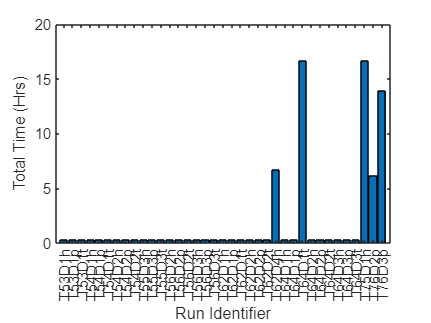

[run_ids_groups, run_ids] = findgroups(data.run_id);
totalTime = splitapply(@max, data.time, run_ids_groups);

bar(run_ids,totalTime,'DisplayName','Time taken to run tests');

% Create ylabel
ylabel({'Total Time (Hrs)'});

% Create xlabel
xlabel({'Run Identifier'});

### Total cycles

This indicates how many total cycles of loading the disc had undergone. Plotting the same graph as before shows that the most common number of total cycles was 1001.

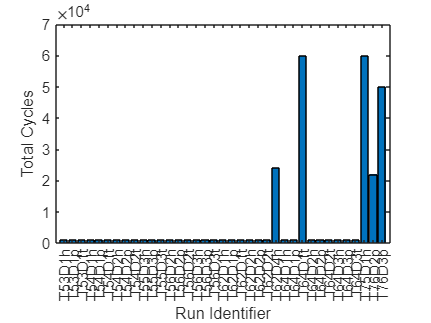

[run_ids_groups, run_ids] = findgroups(data.run_id);
totalCycles = splitapply(@max, data.total_cycles, run_ids_groups);

bar(run_ids,totalCycles,'DisplayName','Total number of cycles per test');

% Create ylabel
ylabel({'Total Cycles'});

% Create xlabel
xlabel({'Run Identifier'});

### Test frequency

By using the results of the above two tests the frequency of each test run can also be calculated. This shows that all the tests ocurred at 1Hz

totalTimeInSeconds = totalTime * 60 * 60

totalTimeInSeconds = 1.0e+04 *

    0.1001
    0.1001
    0.1001
    0.1004
    0.1001
    0.1001
    0.1001
    0.1001
    0.1001
    0.1001


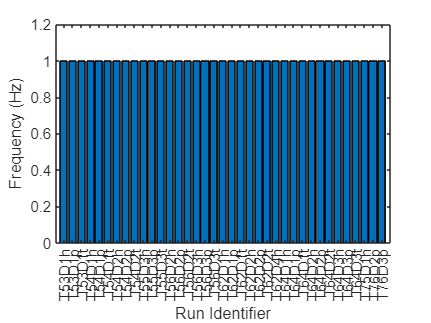

frequency = totalCycles ./ totalTimeInSeconds;

bar(run_ids,frequency,'DisplayName','Frequency used in tests');

% Create ylabel
ylabel({'Frequency (Hz)'});

% Create xlabel
xlabel({'Run Identifier'});

### Step

No idea what this is, just all seems to be the constant 5.

### Position Linear

Presume this is the position of the compressing bit. Plotting for one 

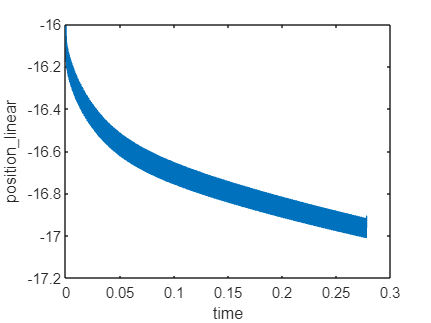

plot(data(data.run_id == "T53D1h", :), "time", "position_linear");

### Load Linear

The load applied to the disc at this time

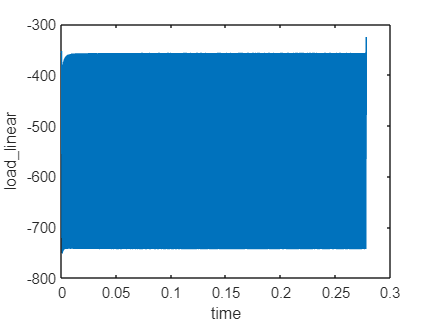

plot(data(data.run_id == "T53D1h", :), "time", "load_linear");

discs = unique(data.disc_id);

healthy = data(data.run_id == "T53D1h", :);

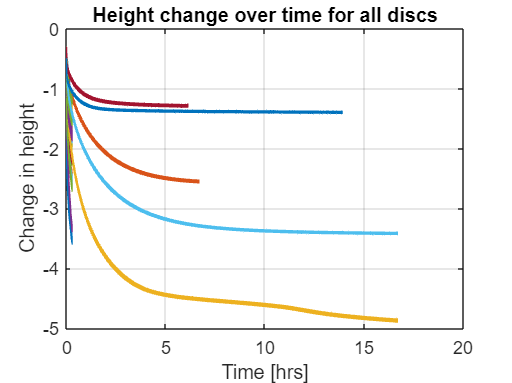

disc_ids = unique(data.disc_id);

for disc_id_index = 1:length(disc_ids)
    plot(data(data.disc_id == disc_ids(disc_id_index), ["TotalTime_hrs_", "DeltaH_mm_"]), "TotalTime_hrs_", "DeltaH_mm_")
    hold on;
end
grid on
xlabel('Time [hrs]')
ylabel('Change in height')
title('Height change over time for all discs')

columns = ["DeltaH_mm_","DiscStrain"]

columns = 1×2 string array
    "DeltaH_mm_"    "DiscStrain"


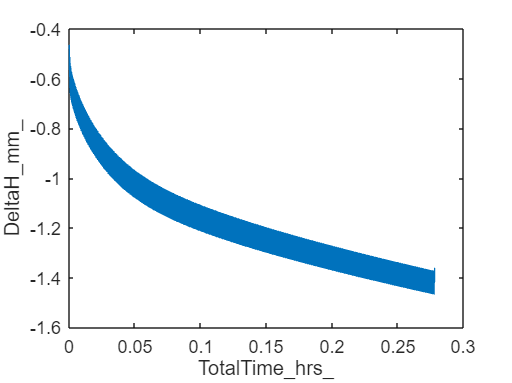

run_ids = unique(data.run_id);
run_id_example = run_ids(1);
disc = data(data.run_id == run_id_example, :);
tiledlayout(size(data, 2) - 1, 1);
for column_index = columns
    plot(disc, "TotalTime_hrs_", column_index(1))
    nexttile
end

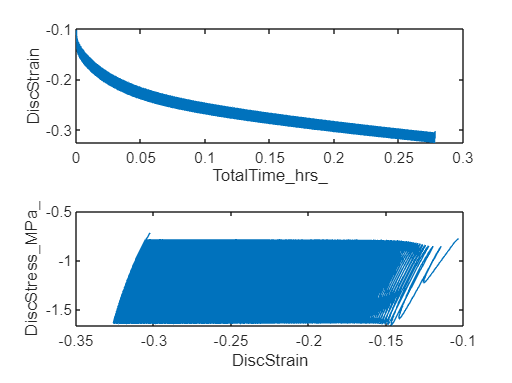

plot(disc, "DiscStrain", "DiscStress_MPa_")

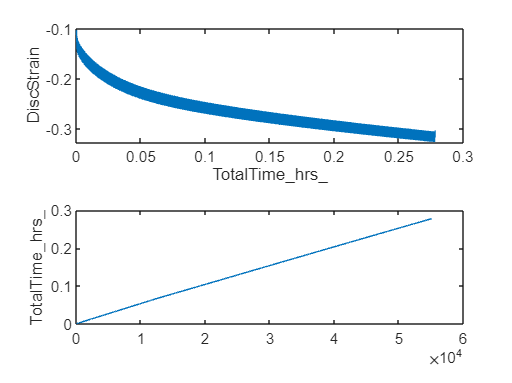

times =     0.2781
    0.2781
    0.2781
    0.2788
    0.2781
    0.2781
    0.2781
    0.2781
    0.2781
    0.2781


plot(disc, "TotalTime_hrs_")